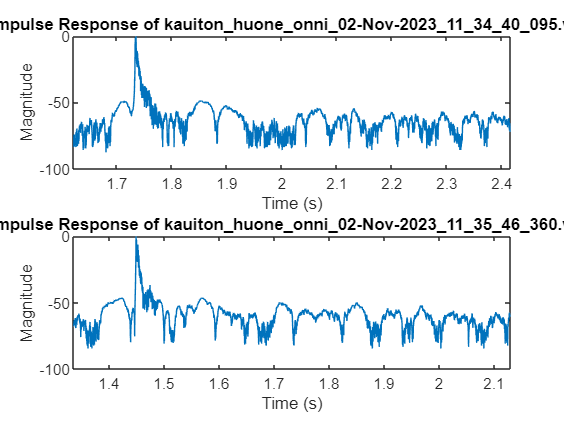

% impulssien piirtäminen

% Load the audio files
% jälkihuomautus! wav-tiedostojen oletetaan löytyvän
% nauhoitukset-kansiosta.
% ko. kansion oletetaan löytyvän samasta hakemistosta, kuin tämän
% tiedoston
filename1 = 'kauiton_huone_onni_02-Nov-2023_11_34_40_095.wav';
filename2 = 'kauiton_huone_onni_02-Nov-2023_11_35_46_360.wav';
[y1, Fs1] = audioread(fullfile('nauhoitukset', filename1));
[y2, Fs2] = audioread(fullfile('nauhoitukset', filename2));

% Calculate the signal energy envelope
energy_envelope1 = conv(y1.^2, ones(10, 1), 'same');
energy_envelope2 = conv(y2.^2, ones(10, 1), 'same');

% Convert to dB
energy_db1 = 10 * log10(energy_envelope1 / max(energy_envelope1));
energy_db2 = 10 * log10(energy_envelope2 / max(energy_envelope2));

% max impulse
[~, start_index1] = max(energy_db1);
[~, start_index2] = max(energy_db2);

time1 = (0:length(energy_db1)-1) / Fs;
time2 = (0:length(energy_db2)-1) / Fs;

delta1 = 5000;
delta2 = 30000;

subplot(2, 1, 1);
plot(time1, energy_db1)
xlim([(start_index1 - delta1) / Fs, (start_index1 + delta2) / Fs])
title(sprintf('Impulse Response of %s', filename1), 'Interpreter', 'none');
xlabel('Time (s)');
ylabel('Magnitude');

subplot(2, 1, 2);
plot(time2, energy_db2);
xlim([(start_index2 - delta1) / Fs, (start_index2 + delta2) / Fs])
title(sprintf('Impulse Response of %s', filename2), 'Interpreter', 'none');
xlabel('Time (s)');
ylabel('Magnitude');